close all
clearvars
% ===================================

img = imread('Mapleleaf.tif');
imshow(img), title('Leaf')

Bound = bwboundaries(img);
Bound = Bound{1};
x = Bound(:, 2); 
y = Bound(:, 1);

hold on

plot(x, y, 'g', 'Linewidth', 3)

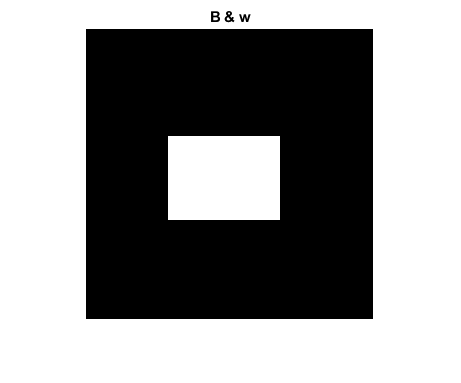

close all
clearvars
% =================================

img = imread('Rect.png');

img_gray = rgb2gray(img);
img_gray = im2double(img_gray);

B = bwboundaries(img_gray);
B = B{1};

x= B(:, 2);
y = B(:, 1);

imshow(img_gray), hold on
plot(x, y, 'b', 'Linewidth', 3)

% ---------------------------------------

Im = imbinarize(img_gray);

imshow(Im), title('B & w')

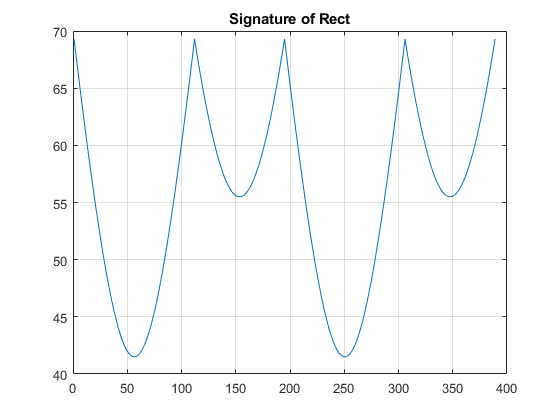


% Detection The center of object

Measure = regionprops(Im, 'Centroid');

X_center = Measure.Centroid(1);
Y_center = Measure.Centroid(2);

Distance = sqrt((x-X_center).^2 + (y - Y_center).^2);

figure,
plot(Distance), grid on, title('Signature of Rect')

close all
clearvars
% =========================

x = [1, -1, -1, 1; 1, 1, -1, -1];
 
target = [1; -1; -1; -1];

w = [0; 0];
b = 0;
alpha = 0.01;

epoch = 0;
cnt = 0;
flag = 1;
while flag == 1
    cnt = 0
    for i = 1:size(x, 2)
        net = b + sum(w .* x(:, i));
        
        if sign(net) ~= target(i)
            w = w + alpha * target(i) * x(:, i);
            b = b + alpha * target(i);
        else
            cnt = cnt + 1;
        end
        
    end
    
    epoch = epoch + 1;
    if epoch > 100 , flag = 0; epoch = 0; end
    if cnt == 4, flag = 0; end
    
end

cnt = 0

cnt = 0

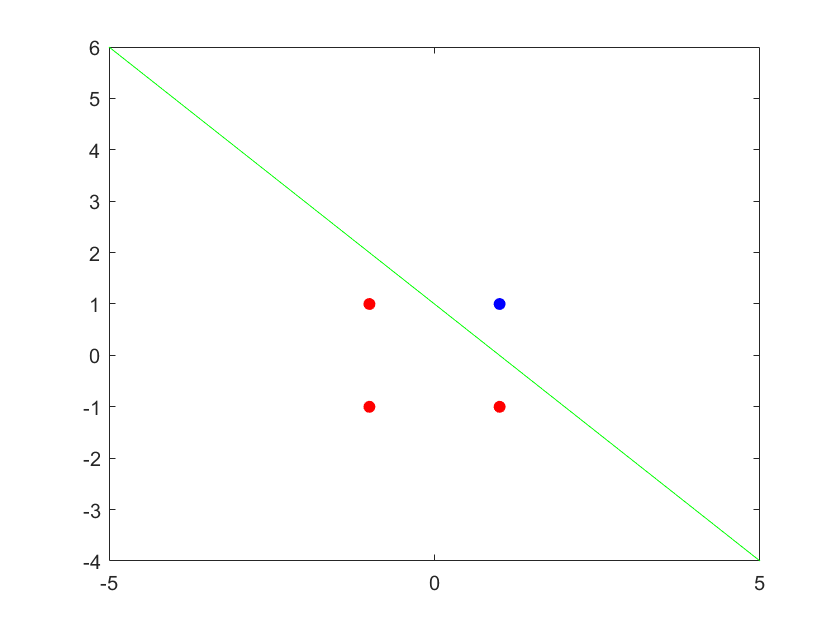


X = linspace(-5, 5);

Y = (w(1)*X + b) / -w(2);
figure,
plot(X, Y, 'g');
hold on
scatter(x(1, 1), x(2, 1), 'blue', 'filled')
scatter(x(1, 2:end), x(2, 2:end), 'red', 'filled')